# Fitting a GPR Model

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

data = readtable("./data/dataSine.xlsx", Sheet="data");
dataTrain = readtable("./data/dataSine.xlsx", Sheet="dataTrain");
dataTest = readtable("./data/dataSine.xlsx", Sheet="dataTest");
whos data dataTrain dataTest

  Name             Size            Bytes  Class    Attributes

  data           200x2              4387  table              
  dataTest        60x2              2147  table              
  dataTrain      140x2              3427  table              



## Task 1

The table `data` has been split into training and test sets: `dataTrain` and `dataTest`. The response variable is `"y"`.

You can use the function `fitrgp` to fit a model using Gaussian process regression.

`gpMdl` `=` `fitrgp``(``data``,``"``ResponseName``"``)`

The `predict` and `loss` functions can be used to predict the response and calculate the loss of the predictions, respectively.

`preds` `=` `predict``(``gpMdl``,``data``)`

`mdlLoss` `=` `loss``(``gpMdl``,``data``)`

Fit model and evaluate at test values.

mdl = fitrgp(dataTrain, "y");

yPred = predict(mdl, dataTest);
mdlMSE = loss(mdl, dataTest)

mdlMSE = 0.1185

Plot the results.

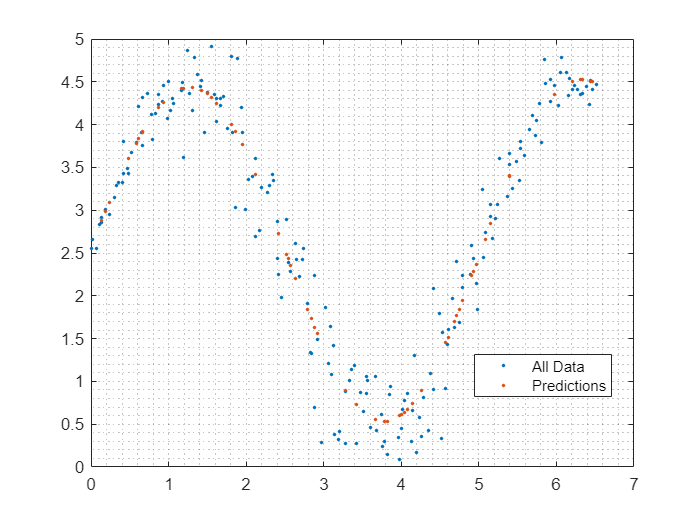

plot(data.x, data.y, ".")
hold on
plot(dataTest.x, yPred, ".")
grid minor
hold off
legend("All Data", "Predictions", "Location", "Best")